%Question 3
clear all;

%Input step values, initial conditions, and calculated values
h = 5;
v = 0;
vold = 0;
p = 1000;
pold = 0;
t = 0;

%Store k values
k1 = [];
k2 = [];
k3 = [];
k4 = [];

%Declare function
func = @Lab6Eqn;

i = 2;

%Implement Runge-Kutta method until the object hits the ground
while p > 0
    v
    p

    k1(i-1) = feval(func,t,v);
    k2(i-1) = feval(func,(t+(h/2)),(v+((k1(i-1)*h)/2)));
    k3(i-1) = feval(func,(t+(h/2)),(v+((k2(i-1)*h)/2)));
    k4(i-1) = feval(func,(t+h),(v+(k3(i-1)*h)));

    vnew = v+(((k1(i-1)+2*k2(i-1)+2*k3(i-1)+k4(i-1))/6)*h);

    %Iterate position and velocity values
    pold = p;
    p = pold-v*h;

    vold = v;
    v = vnew;

    %Iterate founter and time
    i = i+1;
    t = t+5;
    
end

v = 40.7759

p = 1000

v = 56.5779

p = 796.1204

v = 60.9903

p = 513.2311

v = 62.1939

p = 208.2796

v = 62.5205

p = -102.6898

Elapsed time is 0.168005 seconds.


%Question 4
clear all;
tic;

%Input step values, initial conditions, and calculated values
Step = [1,0.1,0.01,0.0001,0.00001];
v = 0;
vold = 0;
p = 1000;
pold = 0;
t = 0;

%Store k values
k1 = [];
k2 = [];
k3 = [];
k4 = [];

%Declare function
func = @Lab6Eqn;

%Store time values
TimeElapsed = [];

%Activate counters
counter = zeros(1,5);
i = 2;

%loop through all step sizes
for j = 1:(length(Step))
    h = Step(j);

    %implement Runge-Kutta method until 21s is reached
    while t < 21
        counter(j) = counter(j) + 1;

        k1(i-1) = feval(func,t,v);
        k2(i-1) = feval(func,(t+(h/2)),(v+((k1(i-1)*h)/2)));
        k3(i-1) = feval(func,(t+(h/2)),(v+((k2(i-1)*h)/2)));
        k4(i-1) = feval(func,(t+h),(v+(k3(i-1)*h)));
    
        vnew = v+(((k1(i-1)+2*k2(i-1)+2*k3(i-1)+k4(i-1))/6)*h);
        
        %Iterate position and velocity values
        pold = p;
        p = pold-v*h;
    
        vold = v;
        v = vnew;
    
        %Update counters
        i = i+1;
        t = t+h;
    end
    %Refresh time
    t = 0;
    TimeElapsed(j) = toc
end

TimeElapsed = 0.0645

TimeElapsed =     0.0645    0.0655


TimeElapsed =     0.0645    0.0655    0.0723


TimeElapsed =     0.0645    0.0655    0.0723    0.7064


TimeElapsed =     0.0645    0.0655    0.0723    0.7064    7.1818


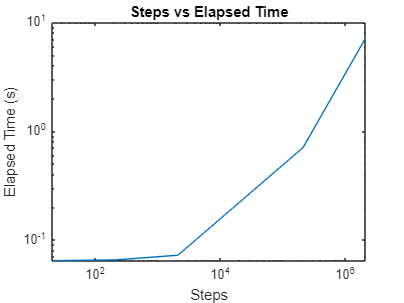


loglog(counter,TimeElapsed)
title('Steps vs Elapsed Time')
xlabel('Steps')
ylabel('Elapsed Time (s)')

%Question 5
clear all;

tic;

%Declare function and time range
func = @Lab6Eqn;
tspan = [0 25];

%implement ode45
[t,v]=ode45(func,tspan,0);

TimeElapsed = toc

TimeElapsed = 0.0905

v

v =          0
    0.0001
    0.0001
    0.0002
    0.0002
    0.0005
    0.0007
    0.0010
    0.0012
    0.0025
